# Projeto final Controle H-inf boost 21/01/2022

Moisés Santin

clear all; close all; clc;
s = tf('s');

%% Planta

g_n = 90;
ct_n = 1.1;

## Planta Gs com as incertezas no modelo variando 30%

p1 = 30;   % Porcentagem para gerar as incertezas
p2 = 30;   % Porcentagem para gerar as incertezas
 
g = ureal('ganho',g_n,'Percentage',p1); 
ct = ureal('Constante_de_Tempo',ct_n,'Percentage',p2);
 
Gs = g / (ct*s + 1)


Gs =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 3 states.
  The model uncertainty consists of the following blocks:
    Constante_de_Tempo: Uncertain real, nominal = 1.1, variability = [-30,30]%, 1 occurrences
    ganho: Uncertain real, nominal = 90, variability = [-30,30]%, 1 occurrences

Type "Gs.NominalValue" to see the nominal value, "get(Gs)" to see all properties, and "Gs.Uncertainty" to interact with the uncertain elements.



## Funções peso

A = 0.02; % Baixas frequencias
M = 0.98; % Altas frequencias
wb = 0.01; % Inclinação


Wp = ((s/M)+ wb) / (s + (A*wb));
Wu = 2;

P = augw(Gs,Wp,Wu)% calcula um modelo de espaço de estados de um plano de LTI aumentado, com funções de ponderação


P =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0002        0        0   -11.25
   x2        0        1        0        0
   x3        0        0        1       -1
   x4        0      1.1        0        1
 
  B = 
          u1     u2
   x1  0.125      0
   x2      0      0
   x3      0      0
   x4      0     -1
 
  C = 
            x1       x2       x3       x4
   y1  0.07837        0        0   -91.84
   y2        0        0        0        0
   y3        0        0        0      -90
 
  D = 
         u1    u2
   y1  1.02     0
   y2     0     2
   y3     1     0
 
  E = 
       x1  x2  x3  x4
   x1   1   0   0   0
   x2   0   0   1   0
   x3   0   0   0   0
   x4   0   0   0   0
 
Input groups:       
    Name    Channels
     U1        1    
     U2        2    
                    
Output groups:      
    Name    Channels
     Y1       1,2   
     Y2        3    
                    
Continuous-time state-space model.



Ptf = tf(P);

## Controlador sensibilidade mista

K = mixsyn(Gs, Wp, Wu, 1);
[K,CL, GAM] = hinfsyn(P, 1, 1)% Calcula um controlador sensibilidade mista para um sistema SISO


K =
 
  A = 
               x1          x2
   x1     -0.0002  -2.168e-19
   x2        1845      -373.2
 
  B = 
              u1
   x1  0.0007478
   x2          0
 
  C = 
           x1      x2
   y1   58.57  -11.82
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


CL =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1     -0.0002           0           0      -11.25           0           0
   x2           0           1           0           0           0           0
   x3           0           0           1          -1           0           0
   x4           0         1.1           0           1      -58.57       11.82
   x5           0           0           0     -0.0673     -0.0002  -2.168e-19
   x6           0           0           0           0        1845      -373.2
 
  B = 
              u1
   x1      0.125
   x2          0
   x3          0
   x4          0
   x5  0.0007478
   x6          0
 
  C = 
            x1    

GAM = 1.0269

## Funções: Sensibilidade S, Sensibilidade Complementar T, função L

Gs.outputdelay = 1.25; % atraso da planta
looptransfer = loopsens(Gs,K); % Já realiza o fechamento da malha com controlador unitário
L = looptransfer.Li;% tira a função L
T = looptransfer.Ti;% tira a função sensibilidade complementar T 
S = looptransfer.Si;% tira a função sensibilidade


KG = K * Gs; % multiplicando o controlador com a planta 
KS = K * S;

## Plotagens

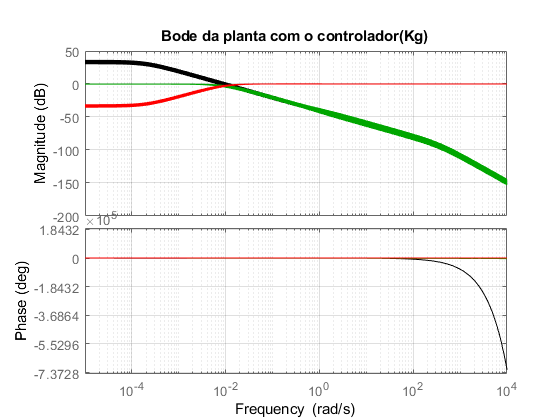

figure (1)
bode(KG,'k') ; hold on % bode da função T
bode(T,'g') ; hold on % bode da função T
grid
bode(S,'r') ; hold on % bode da função S
title('Bode da planta com o controlador(Kg)')

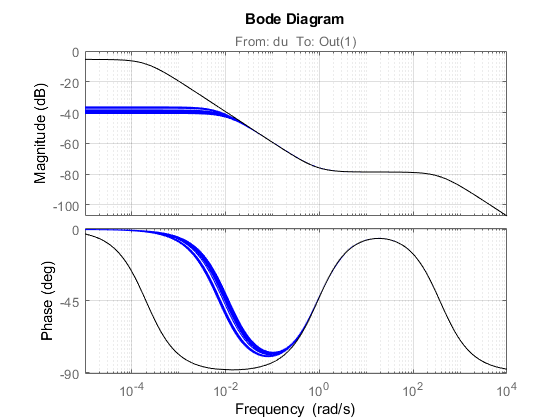


figure(2)
bode (KS, 'b') ; hold on
bode (K, 'k') ; hold on
grid

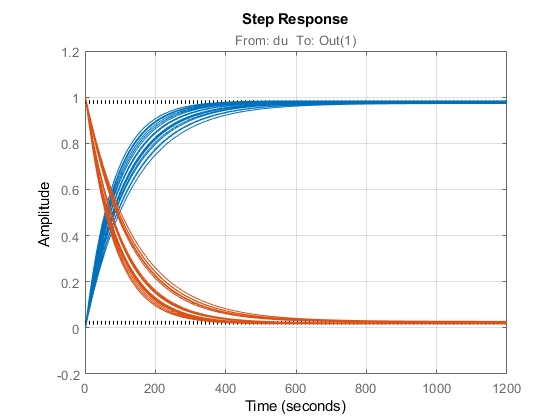



figure(3)
step (T, S)
grid

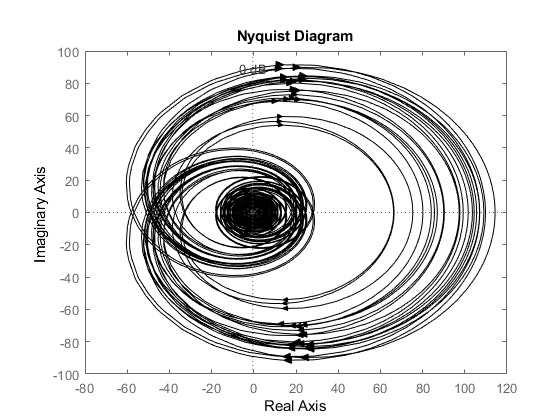


figure(4)
nyquist (Gs, 'k')
grid

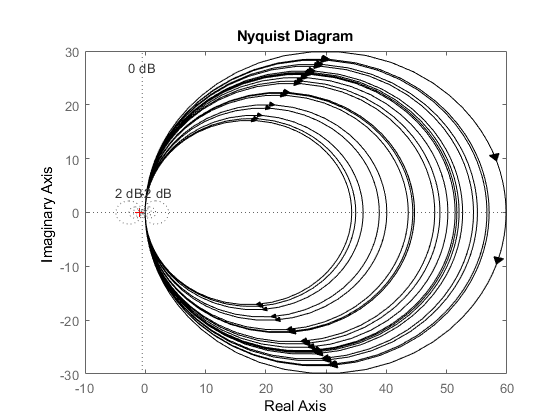


figure(5)
nyquist (KG, 'k')
grid

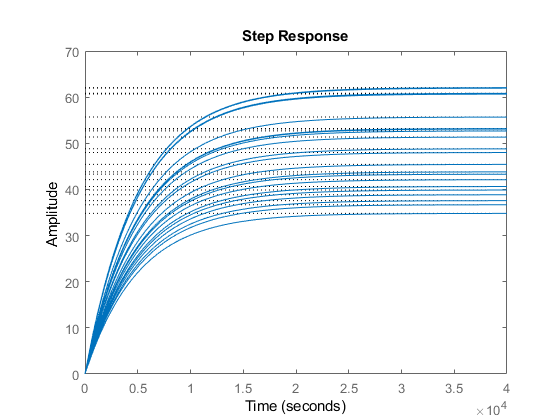


figure(6)
step(KG)

## Simulação

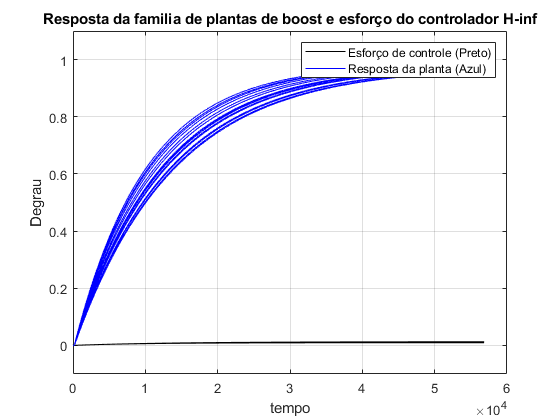

t_run = 500; t_step = 1; Amp_step =1; Ts = 0.5;
sim('simulink_controlehinf'); % chamando a simulação

figure(7)

plot(controle,'k');
hold on;
grid;
title('Resposta da familia de plantas de boost e esforço do controlador H-inf')
ylim ([- 0.1, 1.1]);
ylabel('Degrau');
xlabel('tempo');


plot(planta,'b');
plot(controle1,'k');
plot(planta1,'b');
plot(controle2,'k');
plot(planta2,'b');
plot(controle3,'k');
plot(planta3,'b');
plot(controle4,'k');
plot(planta4,'b');
plot(controle5,'k');
plot(planta5,'b');
plot(controle6,'k');
plot(planta6,'b');
plot(controle7,'k');
plot(planta7,'b');
plot(controle8,'k');
plot(planta8,'b');
plot(controle9,'k');
plot(planta9,'b');
plot(controle10,'k');
plot(planta10,'b');
plot(controle11,'k');
plot(planta11,'b');
plot(controle12,'k');
plot(planta12,'b');
plot(controle13,'k');
plot(planta13,'b');
plot(controle14,'k');
plot(planta14,'b');
plot(controle15,'k');
plot(planta15,'b');

legend('Esforço de controle (Preto)', 'Resposta da planta (Azul)');

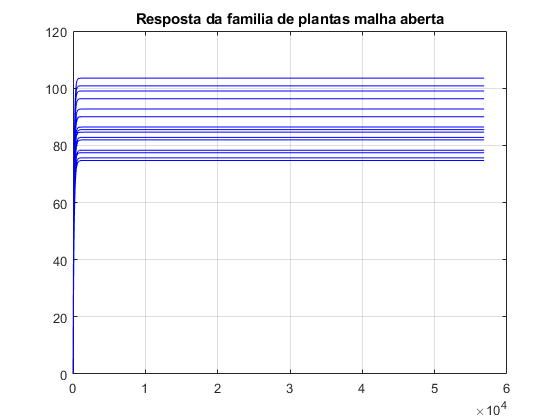


figure(8)

plot(planta16,'b');
hold on
grid
plot(planta17,'b');
plot(planta18,'b');
plot(planta19,'b');
plot(planta20,'b');
plot(planta21,'b');
plot(planta22,'b');
plot(planta23,'b');
plot(planta24,'b');
plot(planta25,'b');
plot(planta26,'b');
plot(planta27,'b');
plot(planta28,'b');
plot(planta29,'b');
plot(planta30,'b');
plot(planta31,'b');
title('Resposta da familia de plantas malha aberta')